# Exercise 4.1 - White noise

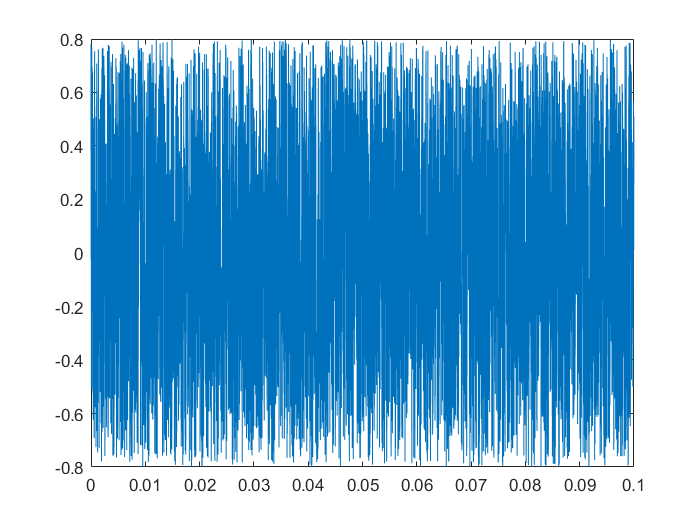

% Maximum amplitude = 0.8 V.
% Frequency = 44100 samples per second (fs = 44.1 kHz).
% Audio fragment of 15 seconds.

% Import audio file.
[whiteNoise, fs] = audioread('audio\ruidoblanco.wav');

% Trim a fragment of the signal of 100 ms (time domain).
N = 0.1 * fs; % # samples
whiteNoiseFrag = whiteNoise(1 : N);

% Play the signal.
sound(whiteNoiseFrag, fs);

% Allocate a vector with the right size to plot the fragment in the time domain.
n = 0 : N - 1;

% Plot the fragment.
t = n / fs;
plot(t, whiteNoiseFrag);

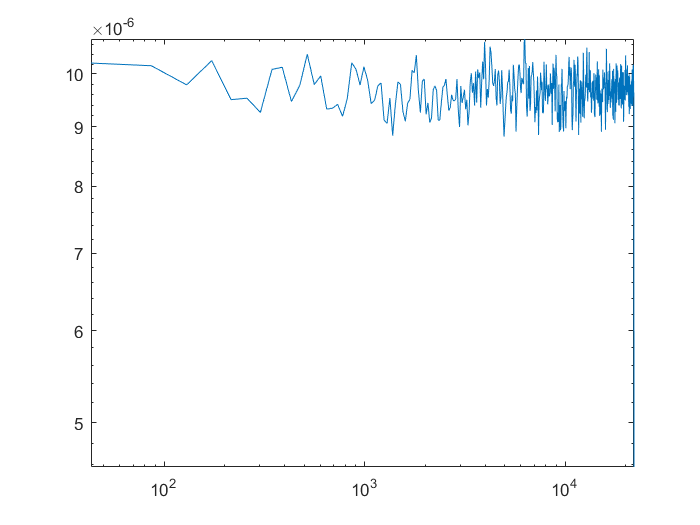


% SPECTRAL ANALYSIS
% Estimate Power Spectral Density (PSD).
[Pxx, f] = pwelch(whiteNoise, 1000, 0, [], fs); 

% Plot DSP, to see the distribution of power as a function of frequency. 
% We shall use logarithmic scale.
loglog(f, Pxx);
axis([0 fs/2 -inf inf]);